# Problema 1.4

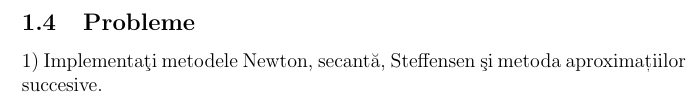

## Metoda lui Newton

function [p, n] = newton_method(f, df, p0, epsilon, Nmax)
    % Rezolvare conform pasilor din pseudo-cod
    % inspirata din Lab12 Metoda Newton-Raphson(pg2)

    i = 1;  % P1: initializare iterator
    while i <= Nmax  % P2: bucla principala
        p = p0 - f(p0)/df(p0);  % P3: pasul Newton
        
        if abs(p - p0) < epsilon  % P4: criteriul de oprire
            n = i;
            return;  % Succes: p este solutia aproximativa
        end

        i = i + 1;   % P5: incrementare
        p0 = p;      % P6: actualizare p0
    end

    % P7: daca nu s-a atins precizia in Nmax pasi
    error('Precizia nu poate fi atinsa cu numarul dat de iteratii.');
end

## Metoda Secanta 

function [p, i] = secant_method(f, p0, p1, epsilon, Nmax)
    % Metoda secantei conform pasilor din pseudo-cod
    %inspirata din Lab12 Metoda secantei (pg3)

    i = 2;                    % P1: initializare contor
    q0 = f(p0); 
    q1 = f(p1);

    while i <= Nmax          % P2: bucla principala
        % P3: calcul noua aproximare
        p = p1 - q1 * (p1 - p0) / (q1 - q0);

        % P4: criteriul de oprire
        if abs(p - p1) < epsilon
            return;  % Succes
        end

        i = i + 1;           % P5: incrementare

        % P6: pregatim urmatoarea iteratie
        p0 = p1;
        q0 = q1;
        p1 = p;
        q1 = f(p);
    end

    % P7: daca nu s-a atins precizia in Nmax pasi
    error('Precizia nu poate fi atinsă cu numărul dat de iterații.');
end

## Metoda Steffensen

function [p, i] = steffensen_method(g, p0, epsilon, Nmax)
    % Metoda Steffensen conform pasilor din pseudo-cod
    %inspirata din Lab12 Metoda lui Steffensen (pg3)

    i = 1;  % P1: initializare contor

    while i <= Nmax  % P2: bucla principala
        % P3: calculam pasii iterativi g(g(...))
        p1 = g(p0);               % p1 := g(p0)
        p2 = g(p1);               % p2 := g(p1)

        % Calculam noua aproximare folosind formula Steffensen
        denom = p2 - 2*p1 + p0;
        if denom == 0
            error('Împărțire la zero.');
        end

        p = p0 - ((p1 - p0)^2) / denom;

        % P4: verificam criteriul de oprire
        if abs(p - p0) < epsilon
            return;  % Succes
        end

        i = i + 1;    % P5: incrementare
        p0 = p;       % P6: actualizare p0
    end

    % P7: nu s-a atins precizia
    error('Precizia nu poate fi atinsa cu numarul dat de iteratii.');
end

## Aproximatii succesive

function [p, n] = approx_succ(g, p0, epsilon, Nmax)
    % Metoda aproximatiilor succesive
    for n = 1:Nmax
        % P1: Calculam urmatoarea aproximatie p = g(p0)
        p = g(p0);

        % P2: Verificam criteriul de oprire |p - p0| < epsilon
        if abs(p - p0) < epsilon
            return;  % P3: Succes, conditia de oprire e indeplinita
        end

        % P4: Pregatim urmatoarea iteratie
        p0 = p;
    end

    % P5: Daca am ajuns aici, nu s-a atins precizia in Nmax pasi
    error('Precizia nu a fost atinsa in %d pasi', Nmax);
end 

f = @(x) x^3 - 2*x - 5;        % f(x): funcția data pentru care vrem f(x) = 0
df = @(x) 3*x^2 - 2;           % f'(x): derivata functiei f
g = @(x) (2*x + 5)^(1/3);      % g(x): functia pentru metoda g(x) = x

% Parametrii algoritmilor
p0 = 2;           % valoare initiala
p1 = 2.5;         % doar pentru metoda secantei
epsilon = 1e-8;   % eroare tolerata
Nmax = 50;        % numar maxim de iteratii





fprintf("METODA NEWTON-RAPHSON\n");

METODA NEWTON-RAPHSON


fprintf("Formula: p_{n+1} = p_n - f(p_n)/f'(p_n)\n");

Formula: p_{n+1} = p_n - f(p_n)/f'(p_n)



f0 = f(p0);
df0 = df(p0);
newton_first = p0 - f0 / df0;
fprintf("Aplicare: p1 = %.4f - f(%.4f)/f'(%.4f) = %.4f - %.4f / %.4f = %.10f\n", ...
        p0, p0, p0, p0, f0, df0, newton_first);

Aplicare: p1 = 2.0000 - f(2.0000)/f'(2.0000) = 2.0000 - -1.0000 / 10.0000 = 2.1000000000



[p_newton, n1] = newton_method(f, df, p0, epsilon, Nmax);
fprintf("Rezultat final: x ≈ %.10f (în %d iteratii)\n", p_newton, n1);

Rezultat final: x ≈ 2.0945514815 (în 4 iteratii)


fprintf("Verificare: f(x) = %.2e\n\n", f(p_newton));

Verificare: f(x) = -8.88e-16





fprintf("METODA SECANTEI\n");

METODA SECANTEI


fprintf("Formula: p = p1 - f(p1)*(p1 - p0)/(f(p1) - f(p0))\n");

Formula: p = p1 - f(p1)*(p1 - p0)/(f(p1) - f(p0))



f_p0 = f(p0);
f_p1 = f(p1);
secant_first = p1 - f_p1 * (p1 - p0) / (f_p1 - f_p0);
fprintf("Aplicare: p2 = %.4f - %.4f*(%.4f - %.4f)/(%.4f - %.4f) = %.10f\n", ...
        p1, f_p1, p1, p0, f_p1, f_p0, secant_first);

Aplicare: p2 = 2.5000 - 5.6250*(2.5000 - 2.0000)/(5.6250 - -1.0000) = 2.0754716981



[p_secant, n2] = secant_method(f, p0, p1, epsilon, Nmax);
fprintf("Rezultat final: x ≈ %.10f (in %d iteratii)\n", p_secant, n2);

Rezultat final: x ≈ 2.0945514815 (in 7 iteratii)


fprintf("Verificare: f(x) = %.2e\n\n", f(p_secant));

Verificare: f(x) = -8.88e-16





fprintf("METODA STEFFENSEN\n");

METODA STEFFENSEN


fprintf("Formula: p = p0 - (g(p0) - p0)^2 / (g(g(p0)) - 2g(p0) + p0)\n");

Formula: p = p0 - (g(p0) - p0)^2 / (g(g(p0)) - 2g(p0) + p0)



g1 = g(p0);
g2 = g(g1);
denom = g2 - 2*g1 + p0;
steff_first = p0 - ((g1 - p0)^2)/denom;
fprintf("Aplicare: p1 = %.4f - (%.4f - %.4f)^2 / (%.4f - 2*%.4f + %.4f) = %.10f\n", ...
        p0, g1, p0, g2, g1, p0, steff_first);

Aplicare: p1 = 2.0000 - (2.0801 - 2.0000)^2 / (2.0924 - 2*2.0801 + 2.0000) = 2.0945695285



[p_steff, n3] = steffensen_method(g, p0, epsilon, Nmax);
fprintf("Rezultat final: x ≈ %.10f (în %d iteratii)\n", p_steff, n3);

Rezultat final: x ≈ 2.0945514815 (în 3 iteratii)


fprintf("Verificare: f(x) = %.2e\n\n", f(p_steff));

Verificare: f(x) = 3.55e-15





fprintf("METODA APROXIMATIILOR SUCCESIVE\n");

METODA APROXIMATIILOR SUCCESIVE


fprintf("Formula: p_{n+1} = g(p_n)\n");

Formula: p_{n+1} = g(p_n)



g_first = g(p0);
fprintf("Aplicare: p1 = g(%.4f) = %.10f\n", p0, g_first);

Aplicare: p1 = g(2.0000) = 2.0800838231


try
    [p_succ, n4] = approx_succ(g, p0, epsilon, Nmax);
    fprintf("Rezultat final: x ≈ %.10f (în %d iteratii)\n", p_succ, n4);
    fprintf("Verificare: f(x) = %.2e\n\n", f(p_succ));
catch e
    fprintf("Eroare: %s\n", e.message);
    fprintf("Metoda NU converge pentru această problemă.\n\n");
end

Rezultat final: x ≈ 2.0945514809 (în 10 iteratii)


Verificare: f(x) = -6.99e-09





fprintf("1. Newton      | Ordin: 2       | Iterații: %2d | Soluție: %.10f\n", n1, p_newton);

1. Newton      | Ordin: 2       | Iterații:  4 | Soluție: 2.0945514815


fprintf("2. Secantă     | Ordin: ~1.618  | Iterații: %2d | Soluție: %.10f\n", n2, p_secant);

2. Secantă     | Ordin: ~1.618  | Iterații:  7 | Soluție: 2.0945514815


fprintf("3. Steffensen  | Ordin: 2       | Iterații: %2d | Soluție: %.10f\n", n3, p_steff);

3. Steffensen  | Ordin: 2       | Iterații:  3 | Soluție: 2.0945514815


if exist('n4', 'var')
    fprintf("4. Aprox. succ.| Ordin: 1       | Iterații: %2d | Soluție: %.10f\n", n4, p_succ);
else
    fprintf("4. Aprox. succ.| Ordin: 1       | Iterații:  -- | Nu a convergent\n");
end

4. Aprox. succ.| Ordin: 1       | Iterații: 10 | Soluție: 2.0945514809
